# **MACHINE LEARNING: PERCEPTRON AND LINEAR REGRESSION**

#### **PERCEPTRON**

#### Submitted by: Jonabel Eleanor B. Baldres

#### App Physics 157 WFY FX 2

%Loading the extracted features of the fruit data
load("Fruit_Properties.mat");

%weights
weight =rand(3,1) * 0.01 ;

%learning rate and epoch setting
learning_rate = 0.01 ;
num_epochs = 10000 ;

%training loop

for epoch = 1:num_epochs
    for i = 1:size(Fruit_Properties,1)
        %compute activation
        activation = dot(Fruit_Properties(i, 1:3), weight);

        %Apply  the activation function which is a step function
        if activation >= 0
            output = 1;
        else 
            output = -1;
        end

        %Calculating weight change
        delta_weight = learning_rate * (Fruit_Properties(i,4)- output) * Fruit_Properties(i,1:3)';

        %updating weights ;
        weight = weight + delta_weight ;

    end
end

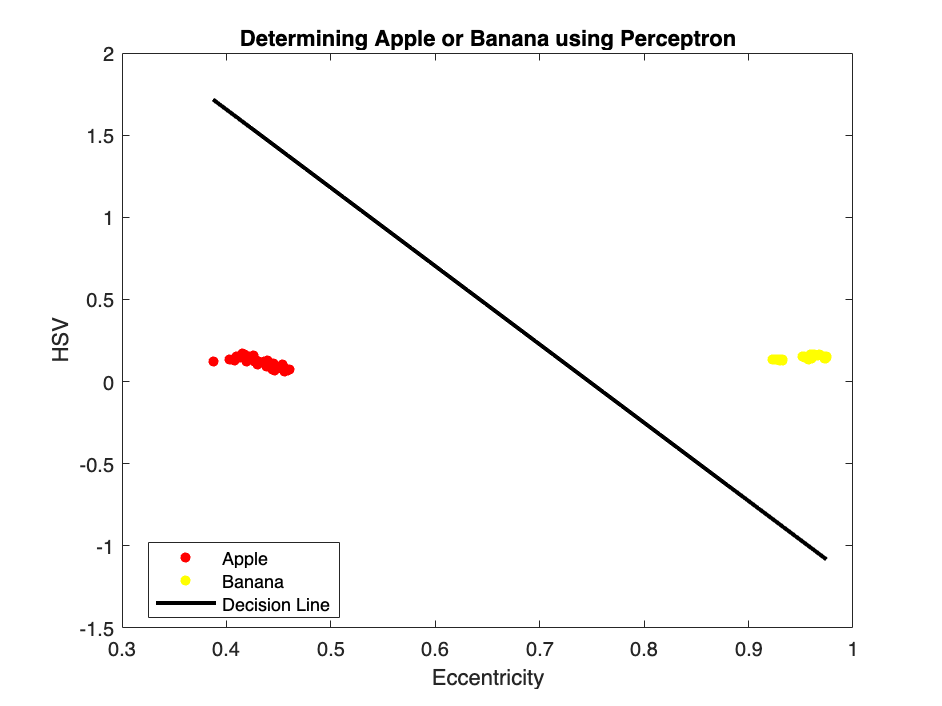

%plotting
figure; 
gscatter(Fruit_Properties(:,2), Fruit_Properties(:,3), Fruit_Properties(:,4), 'ry');
hold on;
xlabel('Eccentricity')
ylabel('HSV')
title('Determining Apple or Banana using Perceptron');
axis 'auto xy';
slope = -(weight(2)./weight(3));
y_intercept = -(weight(1)./weight(3));
xLine = linspace(min(Fruit_Properties(:,2)), max(Fruit_Properties(:,2)),100);
yLine = slope * xLine + y_intercept; 
plot(xLine, yLine, 'k-', 'LineWidth', 2);
legend('Apple', 'Banana', 'Decision Line');
hold off;

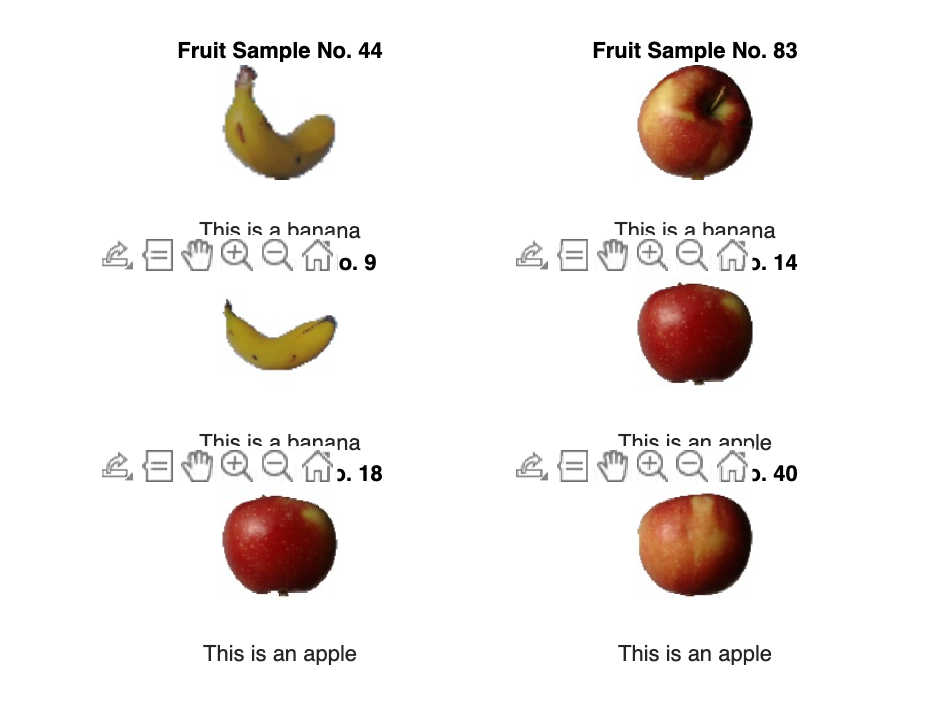

% Testing the Perceptron
% Reading Apple and Banana testing images 
cd('~/Documents/MATLAB/AppleBanana');
fileList = dir('*.jpg'); 
numImages_apple = numel(fileList);
images_apple = cell(numImages_apple, 1);

% Showing 6 random images from the folder
figure;
for i = 1:6
    % selecting random image to predict if it is a banana or apple
    randomIndex = randi([1, numImages_apple]);
    randomImageName = fileList(randomIndex).name;

    % Reading the random image to be able to get their corresponding
    %properties
    fruit = imread(randomImageName);

    subplot(3, 2, i);
    imshow(fruit);
    title(['Fruit Sample No. ', num2str(randomIndex)]);
    
    %Getting the properties
    hsv_fruit = hsv(fruit);
    eccentricity_fruit = eccentricity(fruit);
    unknown_properties = [1 eccentricity_fruit hsv_fruit];
    neuron_dot = dot(unknown_properties, weight);
    if neuron_dot >= 0 
        xlabel("This is a banana");
    else
        xlabel("This is an apple");
    end
end

function hsv_value = hsv(image)
    bw = rgb2gray(image);
    bw = ~imbinarize(bw);
    bw = imfill(bw, 'holes');
    bw = imopen(bw, strel('disk',3));

    hsv_image = rgb2hsv(image);
    hsv = hsv_image(:,:,1);
    hsv_value = mean(mean(hsv(bw)));
end

function eccentricity = eccentricity(image)
    image_gray = rgb2gray(image);
    binary_image = ~imbinarize(image_gray);
    binary_image = imfill(binary_image, 'holes');
    props = regionprops(binary_image, 'Eccentricity');
    eccentricity = props.Eccentricity;
end

